2


$$u\left(x,0\right)=\phi \left(x\right)=1$$


The solution from last question:


$$u\left(x,t\right)=\sum_{n=1}^{\infty } \overset{~}{A_n } \sin \left(n\pi x\right)e^{-{\left(n\pi \right)}^2 t}$$


Plug IC:


$$u\left(x,0\right)=\sum_{n=1}^{\infty } \overset{~}{A_n } \sin \left(n\pi x\right)=1$$



$$\left\langle \sum_{n=1}^{\infty } \overset{~}{A_n } \sin \left(n\pi x\right),\sin \left(m\pi x\right)\right\rangle =\left\langle \phi \left(x\right),\sin \left(m\pi x\right)\right\rangle$$



$$\textrm{LHS}=\sum_{n=1}^{\infty } \overset{~}{A_n } \int_0^1 \sin \left(n\pi x\right)\sin \left(m\pi x\right)\textrm{dx}=\left\lbrace \begin{array}{cc}
0 & \textrm{if}\;m\not= n\\
\frac{1}{2} & \textrm{if}\;m=n
\end{array}\right.$$



$$\textrm{RHS}=\int_0^1 \phi \left(x\right)\sin \left(m\pi x\right)\textrm{dx}=\frac{\overset{~}{A_n } }{2}$$



$$\overset{~}{A_m } =2\int_0^1 \phi \left(x\right)\sin \left(m\pi x\right)\textrm{dx}$$


Plug$\phi \left(x\right)=1$


$$\overset{~}{A_m } =2\int_0^1 \sin \left(m\pi x\right)\textrm{dx}=-\frac{2}{m\pi }{\cos \left(m\pi x\right)}_0^1 =-\frac{2}{m\pi }\left(\cos \left(m\pi \right)-\cos \left(0\right)\right)=\frac{2}{m\pi }\left(1-\cos \left(m\pi \right)\right)=$$


$\overset{~}{A_1 } =\frac{4}{\pi }$, $\overset{~}{A_2 } =0$, $\overset{~}{A_3 } =\frac{4}{3\pi }$, $\overset{~}{A_4 } =0$, $\overset{~}{A_5 } =\frac{4}{5\pi }$, 


$$u\left(x,t\right)=\sum_{n=1}^{\infty } \frac{2}{n\pi }\left(1-{\left(-1\right)}^n \right)\sin \left(n\pi x\right)e^{-{\left(n\pi \right)}^2 t} =\frac{4}{\pi }\sin \left(\pi x\right)e^{-\pi^2 t} +\frac{4}{3\pi }\sin \left(3\pi x\right)e^{-{9\pi }^2 t} +\frac{4}{5\pi }\sin \left(5\pi x\right)e^{-{25\pi }^2 t} +\ldotp \ldotp \ldotp$$


$u\left(x,t\right)=\sum_{n=1}^{\infty } \frac{4}{\left(2n-1\right)\pi }\mathrm{sin}\left(\left(2n-1\right)\pi x\right)e^{-{\left(\left(2n-1\right)\pi \right)}^2 t}$        (6)

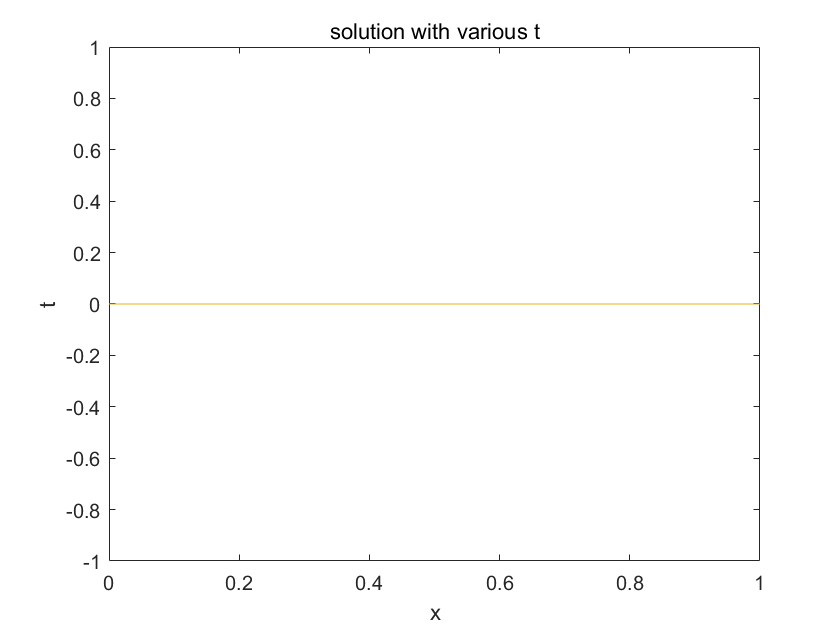

clear
n=50;%set n=50
x=linspace(0,1,500);%generate x

for t=1:500
    %loop for t
    plot(x,u(x,t,n))%plot with each t
    hold on
end
title("solution with various t")
xlabel("x")
ylabel("u(x,t)")
hold off

From the graph we could see the solution will not change with t so t can be any number.

So we set t=2

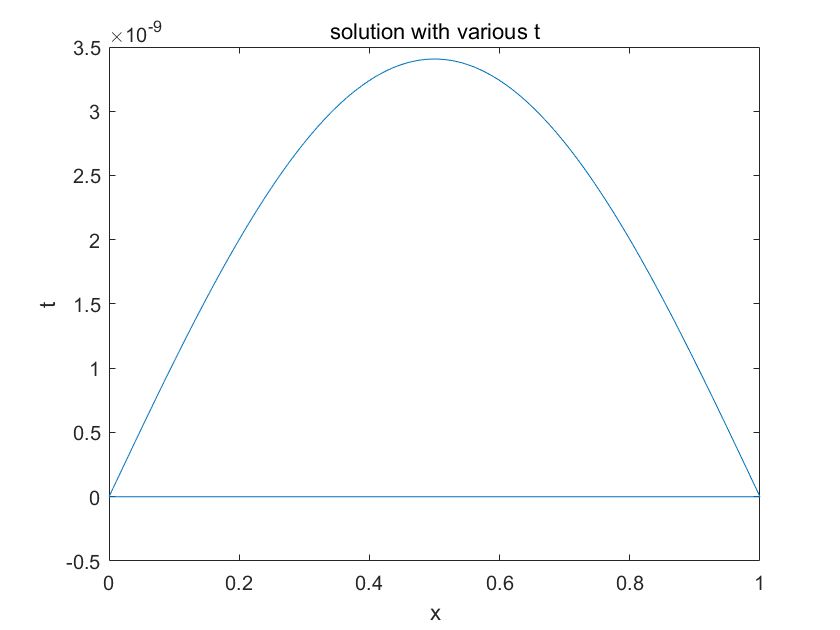

t=2;%set t=2
for n=1:50
    %loop for n
    plot(x,u(x,t,n))%plot with each n
    hold on
end
title("solution with various n")
xlabel("x")
ylabel("u(x,t)")

function [s]=u(x,t,n)
%equation (6)
    s=0;%initialize the sum
    for j = 1:n
        %loop of n
        s=s+4/((2*n-1)*pi)*sin((2*n-1)*x*pi).*exp(-((2*n-1)*pi)^2*t); 
        %add sum together       
    end
end